# Digital Modulation System

## Modulating Signal (display graph)

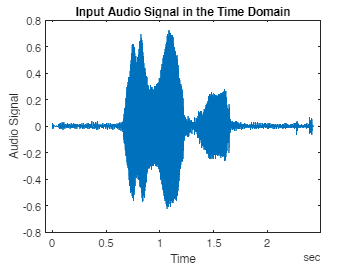

% input audio signal in time domain
[y, Fs] = audioread('New-Recording.wav');
info = audioinfo("New-Recording.wav");
t = 0:seconds(1/Fs):seconds(info.Duration);
t = t(1:end-1);
clf;
figure
plot(t,y); xlabel('Time'); ylabel('Audio Signal'); title('Input Audio Signal in the Time Domain')

% input audio signal in the frequency domain
audio_length = length(y);
df = Fs/audio_length;

audio_freq = -Fs/2:df:Fs/2-df;
clf;
figure
audio_FFT = fft(y);
plot(audio_freq,abs(audio_FFT));
title('Input Audio Signal in the Frequency Domain');
xlabel('Frequency(Hz)');
ylabel('Amplitude');

## Encoding the signal

### Manchester

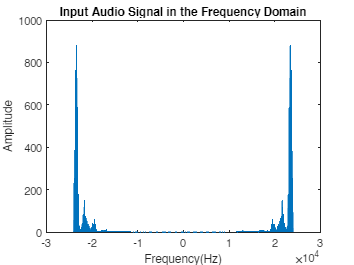

fid  = fopen("New-Recording.wav", 'r');
data = fread(fid, [1, Inf], 'uint8');
fclose(fid);
bit = uint8(rem(floor((1 ./ [128, 64, 32, 16, 8, 4, 2, 1].') * data), 2))

bit = bit(:);

% reshaping
bit_reshape = reshape(bit.',1,[])

### NRZ

### RZ

## Modulating the signal

### 2BPSK

### QPSK

### 16PSK

### 4FSK

### 4QAM

### 8QAM

### 16QAM

## Adding noise 

### SNR = 0dB, 2dB, 5dB, 10dB, -2dB, -5dB, -10dB

% 0dB
% 2dB